# ROOM ACUSTICS:

## Chapter 3: Wave Theory

© Manuel A. Sobreira Seoane, Jan 2020.

### Resonance Frequencies in rectangular rooms.

For a rectangular room with dimensions Lx,Ly, Lz, the resonance frequencies are calculated as:

$ f= \frac{c}{2} \sqrt{\left [ \left(\frac{n_x }{L_x} \right)^2 +
   \left(\frac{n_y }{L_y} \right)^2 +\left(\frac{n_z}{L_z}
   \right)^2 \right ]} \; \quad n_x,n_y,n_z=0 \cdots \infty
$                           (1)

% Room Dimensions:
Lx=10;
Ly=5;
Lz=3.5;
c=343.9832; % Speed of sound, t=20 Degrees Celsius. 
Nmax=3;              % Calculations up to nx=ny=nz=Nmax
nx=0:Nmax;
ny=0:Nmax;
nz=0:Nmax;
[Nx,Ny,Nz]=meshgrid(nx,ny,nz);
Nxyz=[Nx(1:end)' Ny(1:end)' Nz(1:end)'];    %Triplets of all nx, ny,nz up to Nmax

fr=c*sqrt(sum([Nxyz(:,1)/Lx Nxyz(:,2)/Ly Nxyz(:,3)/Lz].^2,2))/2;            % Equation (1)
[f,I]=sort(fr);
N=Nxyz(I,:);
Nf=array2table([N f],'VariableNames',{'nx', 'ny','nz','f'})                 % Results stored in a table

Nf = 64×4 table
    nx    ny    nz      f   
    __    __    __    ______

    0     0     0          0
    1     0     0     17.199
    0     1     0     34.398
    2     0     0     34.398
    1     1     0     38.458
    2     1     0     48.647
    0     0     1      49.14
    3     0     0     51.597
    1     0     1     52.063
    0     1     1     59.984
    2     0     1     59.984
    3     1     0     62.012
    1     1     1     62.401
    0     2     0     68.797
    2     1     1     69.147
    1     2     0     70.914


### Mode Shapes:3

The wave equation has a solution for each resonance frequency which describes the behaviour of the sound field  inside the room at each particular resonance:

$p_{n_xn_yn_z}(x,y,z)=C \cdot  cos(\frac{n_x x\, \pi}{L_x})cos(\frac{n_y y \, \pi}{L_y})cos(\frac{n_z z\, \pi}{L_z})$                       (2)

#### Axial and tangential modes:

First, let as show how axial and tangential modes look like. Axial modes propagate along on axis (so only one of nx,ny,nz is non zero) and tangential modes propagate in a plane (one of the nx,ny,nz is zero). Next, nz=0, so axial and tangential modes envolving propagation along the XY plane are shown. 

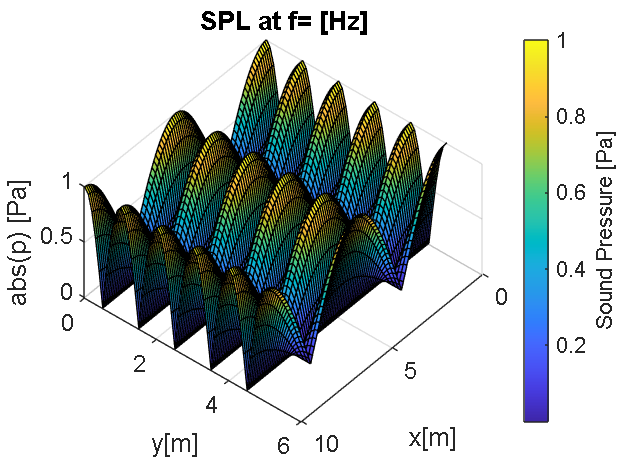

nx=2; ny=5; 
% Grid of calculation points:
res=0.1;                %   Resolution of the grid
x=0:res:Lx;             %   x axis
y=0:res:Ly;             %   y axis
[X,Y]=meshgrid(x,y);    %   Grid XY plane

p=cos(nx*pi*X/Lx).*cos(ny*pi*Y/Ly);              % Eq (2), nz=0; 

%  The mode shape is shown using a surface grahic (surf).
surf(X,Y,abs(p),'FaceColor','interp','EdgeColor','k');
view([-230 60]);
xlabel('x[m]'); ylabel('y[m]');
% We look for the resonance frequency of the selected mode to include it in
% the title of the graphic.
ind=find(Nf.nx==nx & Nf.ny==ny & Nf.nz==0); 
fnxny=f(ind);
title(sprintf('SPL at f=%0.2f [Hz]',fnxny));
set(gca,'FontSize',16); zlabel('abs(p) [Pa]');
h2 = colorbar; set(get(h2,'label'),'string','Sound Pressure [Pa]'); 

#### Oblique Modes:

nx=2; ny=2; nz=1;
z=0:res:Lz;
fnxnynz=c*sqrt(sum([nx/Lx ny/Ly nz/Lz].^2,2))/2;        % Resonance at the specific nx ny nz
[X,Y,Z]=meshgrid(x,y,z);                                % Volume grid 
pxyz=cos(nx*pi*X/Lx).*cos(ny*pi*Y/Ly).*cos(nz*pi*Z/Lz); % Sound pressure 


The sound pressure inside a room is a volumetric function depending on x, y, z. To show it Matlab provides the functions* isosurface *and *slice. *Next, both are combined to get a visualization of the 3D sound field of a single mode:

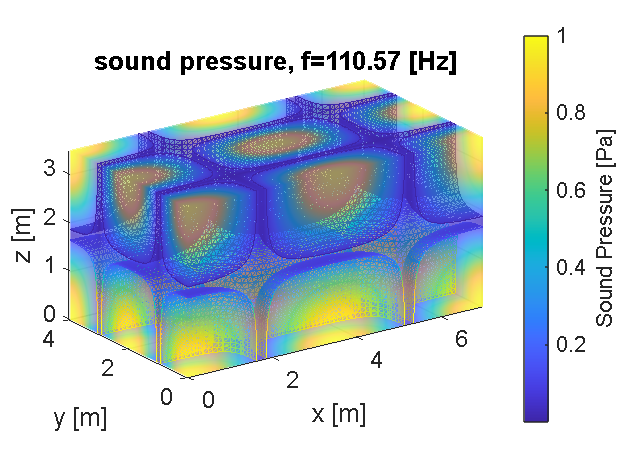

% Isosurface provides here the structure of surfaces of equal pressure
equalpressure=0.1;
[faces,verts,colors] = isosurface(X,Y,Z,abs(pxyz),equalpressure,cos(nz*pi*Z/Lz));
% Slice
h=slice(X,Y,Z,abs(pxyz),[0 Lx],[0 Ly],[0 Lz]); axis equal;
set(h,'FaceLighting','gouraud');
set(h,'FaceColor','interp','EdgeColor','none','Facealpha',0.5); hold on;
patch('Faces',faces,'Vertices',verts,'FacevertexCData',colors,'EdgeColor',...
    'interp','FaceColor','none'); view([-35 20]); colorbar; 
hold off;
set(gca,'FontSize',16); xlabel('x [m]');ylabel('y [m]');zlabel('z [m]');
title(sprintf('sound pressure, f=%0.2f [Hz]',fnxnynz));
h2 = colorbar; set(get(h2,'label'),'string','Sound Pressure [Pa]');

### Frequency Response: 

For a given frequency, the contribution of several modes are added to obtain the sound pressure level. The absolute value of the frequency response of a single mode can be estimated from:

$|p_n(x,y,z,\omega)|= \frac{c^2 \; Q_0 \; \rho \; \omega \; \psi_n(x,y,z)}{V \left[ 4 \omega^2_n k^2_n + (\omega^2 -
  \omega^2_n)^2 \right ]^{1/2}}$                                               (3)

and the  conttribution of all the modes is obtained by superposition: 

$p_t(x,y,z,\omega)= \sum_{n=0}^ \infty p_n(x,y,z,\omega)$                                                            (4).

In eq (3):

- $Q_0$ is the volume velocity of the source ($m^3/s$); 

- *V, *the volume of the room.

- $\omega_n= 2 \pi f_n$: The (angular) resonance frequency of the n-th resonant mode.

- $k_n$is the damping factor of each mode. Depends on the absorption (boundary conditions) of the walls,

- $\psi_n(x,y,z)= \cos (\frac{n_x \pi x}{L_x}) \cdot \cos (\frac{n_y \pi y}{L_y}) \cdot \cos (\frac{n_z \pi z}{L_z}) \phi(x_o,y_o,z_o)$        (5)

- $\phi=\cos (\frac{n_x \pi x_o}{L_x}) \cdot \cos (\frac{n_y \pi
  y_o}{L_y}) \cdot \cos (\frac{n_z \pi z_o}{L_z})$                                 (6)

- $(x_o,y _o,z_o)$: source position

- $(x,y ,z)$: position of an arbitrary receiver (observer) inside the room. 

First, lets see the frequency response for those points where $\psi_n(x,y,z)=1$, i.e. the source is placed at (0,0,0) and the receiver can be placed at (Lx,Ly,Lz). 

kn=0.01*ones(size(Nf.f));      % Damping factor of each mode
Q=1e-3;                                             % Volume velocity of the Source
V=Lx*Ly*Lz;                                         % Volume of the Room
wn=2*pi*Nf.f;                                       % Angular frequency (resonances)
Nofresonances=length(wn);                           % Number of resonances calculated.
fi=0:0.1:max(wn)/(2*pi);                            % Frequency axis to calculate the response
w=2*pi*fi;                                          % Angular frequency (freq. axis)   
respp=zeros(length(wn),length(w));                  % Setting up matrix to store the contribution of each mode.
Lresp=zeros(length(wn),length(w));                  % respp in decibels.
Lpf=zeros(1,length(w));                             % Freq. response in decibels.
for i=1:Nofresonances,
   respp(i,(1:length(w)))=Q*w./sqrt((w-wn(i)).^2+4*wn(i)*kn(i).^2);         % Equation 3
end

Next, all the responses of the modes are added and the sound pressure level calculated: 

Lresp=20*log10(abs(respp)/2e-5);            % Equation (3), responses of each mode.
Lpf=20*log10(abs(sum(respp,1))/2e-5);       % Equation (4) in decibels.     

Let's plot the results: 

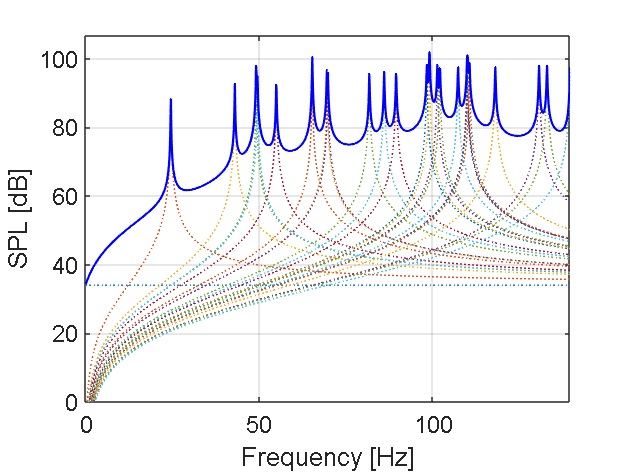

plot(fi,Lresp,':');
hold on;
h=plot(fi,Lpf,'LineWidth',1.5,'Color','b');hold off; 
axis([0 max(fi) 0 max(Lpf)+5]);
set(gca,'FontSize',16); grid; xlabel('Frequency [Hz]'); ylabel('SPL [dB]');

If we change the position of the source or the receiver, the frequency response will change. 

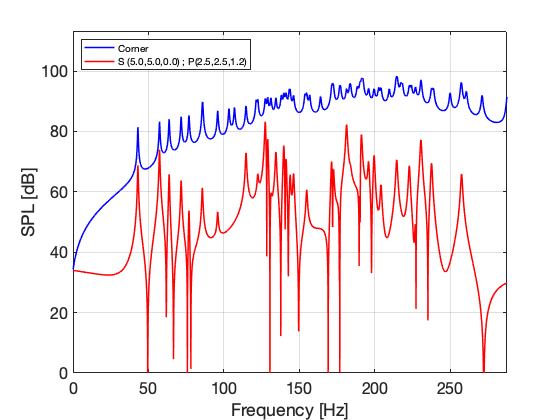

% Source position, posicioón de la fuente:
xs=5; ys=5; zs=0;
% Receiver, P, posición del receptor:
xp=2.5; yp=2.5; zp=1.2; 

resppSP=zeros(Nofresonances,length(w));         % Freq. Response between S and P
Lpsr=zeros(1,length(w));
for i=1:Nofresonances,
   % Eqs (4) and (5):
   Areceiver=cos(Nf.nx(i)*pi*xp/Lx)*cos(Nf.ny(i)*pi*yp/Ly)*cos(Nf.nz(i)*pi*zp/Lz);
   Asource=cos(Nf.nx(i)*pi*xs/Lx)*cos(Nf.ny(i)*pi*ys/Ly)*cos(Nf.nz(i)*pi*zs/Lz);
   % Eq. (3):
   resppSP(i,(1:length(w)))=Q*w./sqrt((w-wn(i)).^2+4*wn(i)*kn(i).^2)*Asource*Areceiver;
end
% Superposition, Eq (4):
% p_sr=sum(resppSP,1); 
Lpsr=20*log10(abs(sum(resppSP,1))/2e-5);          % Freq. Response in decibels. 

% PLOTING RESULTS:
plot(fi,Lpf,'LineWidth',1.5,'Color','b'); hold on;
plot(fi,Lpsr,'LineWidth',1.5,'Color','r'); hold off; 
axis([0 max(fi) 0 max(Lpf)+15]);yr=ylim;
set(gca,'FontSize',16); grid; xlabel('Frequency [Hz]'); ylabel('SPL [dB]'); grid on; 
h=legend('Corner',sprintf('S (%0.1f,%0.1f,%0.1f) ; P(%0.1f,%0.1f,%0.1f)',xs,ys,zs,xp,yp,zp),'Location','northwest','FontSize',10);

#### Frequency Response and sound pressure patterns

Now, let us show the relation between the frequency response and the sound pressure distribution inside a room. To do so, we assume that a sound source placed in one of the corners of the room is emmiting a pure tone with frequency f=ft:

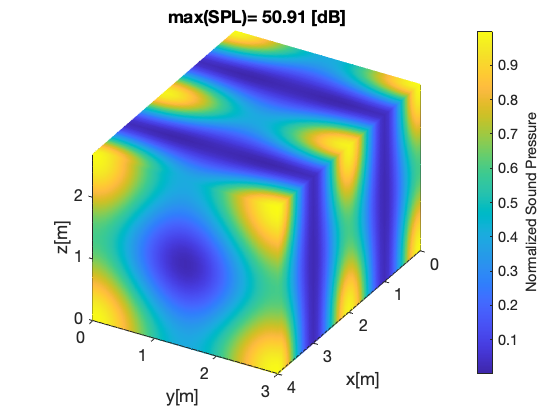

ft=105;
nofres=10;      % the resonances around ft are considered.
ind=find(f<(ft+nofres) & f>(ft-nofres));
pattern=zeros(size(X));
for i=1:length(ind),
   aux=(Q*2*pi*ft./sqrt((2*pi*ft-wn(ind(i))).^2+4*wn(ind(i))*kn(ind(i)).^2)*cos(Nf.nx(ind(i))*pi*X/Lx).*cos(Nf.ny(ind(i))*pi*Y/Ly).*cos(Nf.nz(ind(i))*pi*Z/Lz)).^2;
   pattern=aux+pattern;
end
% Maximum  of SPL:
fn=max(max(max(abs(pattern))))+eps;
M=20*log10(fn/2e-5);


% Plotting the results:
h=slice(X,Y,Z,abs(pattern)/fn,[0 Lx],[0 Ly],[0 Lz]);
set(h,'FaceLighting','gouraud');
box on;
title(sprintf('max(SPL)= %0.2f [dB]',M));

set(h,'FaceColor','interp','EdgeColor','interp');axis equal; colorbar;
set(gca,'FontSize',16);
xlabel('x[m]');ylabel('y[m]');zlabel('z[m]');
h2 = colorbar; set(get(h2,'label'),'string','Normalized Sound Pressure'); 
view([120 30]);

#### Acoustic Decays.

Next, the process of acoustic decay from the point of view of wave theory is shown. Each mode, decays following a decreasing exponential:

$h_{model}=\sum\limits_{i=1}^{n} A_i \cos(2\pi f_it+\phi_i)\exp(\frac{-3 ln 10}{T_i}t)$,              (7)

Where , for each decaying mode considered;

- *Ai: *amplitude at the position of the receiver.

- $\phi_i$: phase at the position of the receiver.

- *fi*: resonance frequencies  

- *Ti: *Reverbertation time.

fs=16000;                % Sampling Frequency   
T=1;                    % Length (seconds) of the decay
t=(0:1/fs:T);        % time 
% Choosing resonances from
fromresonance=2;
toresonance=21;
Ti=1;

fri=Nf.f(fromresonance:toresonance);
N=length(t);
Nr=length(fri);                      % Number of resonances in the acoustic decay
phi=zeros(size(fri));

Let's try to match the real behaviour of the individual decays. As axial, tangential and oblique modes envolves a different number of surfaces, their attenuation, i.e. the reverberation time of each mode will be different. We are modelling this using a statistical approach. For a group of modes, we will asume a normal distribution of mean Ti and variance=v.

The function *randn(m,n)  *generates a normal distributed  m x n matrix with 0 mean and variance=1. 

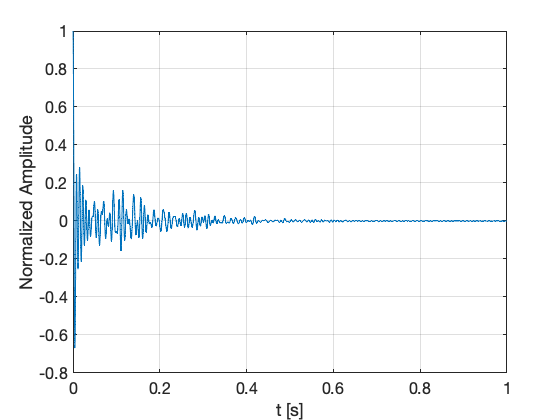

v=0.1;                                % Variance of the RT of the modes. 
TRi=Ti+randn(1,length(fri))*v;  % Normal distribution, mean=Ti and variance v of Ti.
Ai=ones(size(fri));
h=zeros(Nr,N);  
for ii=1:Nr
    h(ii,:)=Ai(ii)*cos(2*pi*fri(ii)*t+phi(ii)).*exp(-3*log(10)*t/(TRi(ii)));
end
x=sum(h,1);
plot(t,x/max(x)); grid;xlabel('t [s]'); ylabel('Normalized Amplitude'); set(gca,'FontSize',16);

Now, the reverse backwards integration (see the standard UNE EN ISO 3382-1) is performed: 

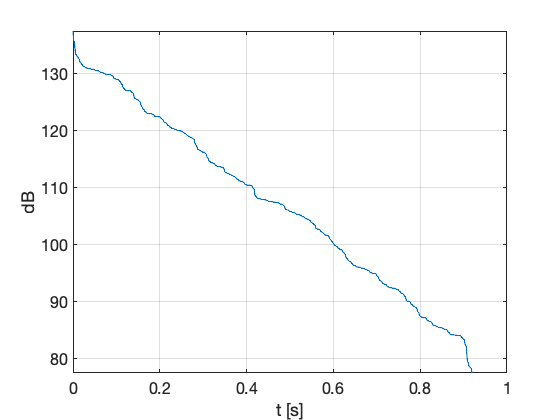

yint=10*log10(cumsum(x(end:-1:1).^2)/4e-10);
ydb=yint(end:-1:1); 
plot(t,ydb);xlabel('t [s]'); ylabel('dB'); set(gca,'FontSize',16); 
axis([0 T max(ydb-60) max(ydb)]);grid

#### References:

- Heinrich Kuttruff. Room Acoustics, 5th edition (chapter 3, Sound Waves in a Room).

- Kob M., Vörlander M. "Band filters and short reverberation times. "Acustica united with Acta Acustica, 86:350–357, 2000. 	

- Sobreira Seoane M.A., Pérez Cabo D, Jacobsen F. "The Influence of the group delay of digital filters on acoustic decay measurements". Applied Acoustics, 2012. [LINK](http://orbit.dtu.dk/files/9737803/37466d01.pdf).

*© Manuel A. Sobreira Seoane, January 2020.*